# Postprocessing and plotting of simulink

this form of script gives us better control of how many plot do we wanna draw at one time.

### Postprocessing

%% Extract data from workspace — convert Timeseries to arrays
if isa(tout,         'timeseries'), tout         = tout.Data;         end
if isa(PSupply,      'timeseries'), PSupply      = PSupply.Data;      end
if isa(PDemand,      'timeseries'), PDemand      = PDemand.Data;      end
if isa(PSell,        'timeseries'), PSell        = PSell.Data;        end
if isa(PBuy,         'timeseries'), PBuy         = PBuy.Data;         end
if isa(T_tes_out,    'timeseries'), T_tes_out    = T_tes_out.Data;    end

% Cavern pressure — derive from m_air if not directly logged
has_mass = exist('m_air_out', 'var');
if has_mass
    if isa(m_air_out, 'timeseries'), m_air_out = m_air_out.Data; end
    if ~exist('p_store_out', 'var')
        p_store_out = m_air_out * R_air * T_amb / V_cavern;
    end
end
if exist('p_store_out', 'var') && isa(p_store_out, 'timeseries')
    p_store_out = p_store_out.Data;
end

% Optional mass flow / energy split outputs
has_flows  = exist('mdot_charge_out','var')  && exist('mdot_discharge_out','var');
has_energy = exist('P_thermal_out','var')    && exist('P_exergy_out','var');
if has_flows
    if isa(mdot_charge_out,    'timeseries'), mdot_charge_out    = mdot_charge_out.Data;    end
    if isa(mdot_discharge_out, 'timeseries'), mdot_discharge_out = mdot_discharge_out.Data; end
end
if has_energy
    if isa(P_thermal_out, 'timeseries'), P_thermal_out = P_thermal_out.Data; end
    if isa(P_exergy_out,  'timeseries'), P_exergy_out  = P_exergy_out.Data;  end
end

%% Derived energy quantities (used by pie charts and deficit plot)
P_DirectSupply = min(PSupply, PDemand);
P_Deficit      = max(0, PDemand - PSupply);
P_ICAES        = max(0, P_Deficit - PBuy);
P_Surplus      = max(0, PSupply - PDemand);
P_ToStorage    = max(0, P_Surplus - PSell);

E_DirectSupply = sum(P_DirectSupply);
E_ICAES        = sum(P_ICAES);
E_Bought       = sum(PBuy);
E_ToStorage    = sum(P_ToStorage);
E_Sold         = sum(PSell);

disp('Data extracted and calculated. Ready to plot.');

Data extracted and calculated. Ready to plot.


## Simulation Parameters Used

%% Simulation Parameters Used
fprintf('Design Configuration File: %s\n', design_params_file);

Design Configuration File: design_params\design_param1.m


fprintf('Maximum Cavern Pressure (p_store_max): %.1f bar\n', p_store_max / unit("bar"));

Maximum Cavern Pressure (p_store_max): 100.0 bar


fprintf('Cavern Volume (V_cavern): %.2e m^3\n', V_cavern / unit("m^3"));

Cavern Volume (V_cavern): 5.00e+06 m^3


fprintf('TES Volume (V_tes): %.1f m^3\n', V_tes / unit("m^3"));

TES Volume (V_tes): 50000.0 m^3


fprintf('TES Mass (m_tes): %.3e kg\n', m_tes / unit("kg"));

TES Mass (m_tes): 1.080e+08 kg


fprintf('Max TES Temperature (T_tes_max): %.1f °C\n', T_tes_max / unit("K") - 273.15);

Max TES Temperature (T_tes_max): 499.9 °C


fprintf('Expansion Inlet Temperature (T_expand): %.1f °C\n', T_expand / unit("K") - 273.15);

Expansion Inlet Temperature (T_expand): 99.9 °C


fprintf('Compressor Efficiency (eta_comp): %.1f%%\n', eta_comp * 100);

Compressor Efficiency (eta_comp): 83.3%


fprintf('Expander Efficiency (eta_exp): %.1f%%\n', eta_exp * 100);

Expander Efficiency (eta_exp): 82.0%


fprintf('Transmission Efficiency (eta_tran): %.1f%%\n', eta_tran * 100);

Transmission Efficiency (eta_tran): 97.0%


fprintf('Pipe Diameter (D_pipe): %.2f m\n', D_pipe / unit("m"));

Pipe Diameter (D_pipe): 50.00 m


fprintf('Flow Velocity (v_flow): %.1f m/s\n', v_flow / (unit("m")/unit("s")));

Flow Velocity (v_flow): 2000.0 m/s


fprintf('Grid Charging Power Limit (P_limit): %.1f MW\n', P_limit / unit("MW"));

Grid Charging Power Limit (P_limit): 300.0 MW


fprintf('Polytropic Index (n_poly): %.2f\n', n_poly);

Polytropic Index (n_poly): 1.14


fprintf('Cable Voltage (Cablevoltage): %.1f kV\n', Cablevoltage);

Cable Voltage (Cablevoltage): 345000.0 kV


fprintf('Cable Resistance per km (Rprime): %.1f mOhm/km\n', Rprime);

Cable Resistance per km (Rprime): 0.0 mOhm/km


fprintf('Cable Length (Cablelength): %.1f km\n', Cablelength);

Cable Length (Cablelength): 100000.0 km


### Plot: System State Overview (Supply/Demand, Pressure, TES Temp, Buy/Sell)

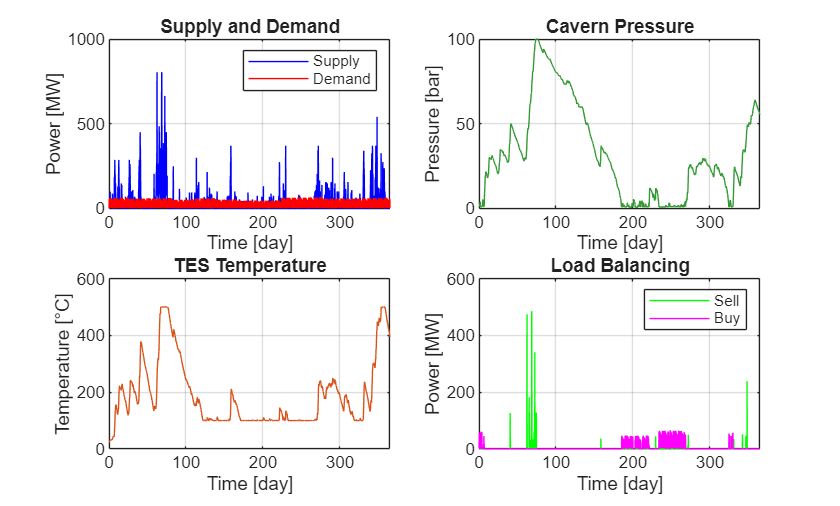

%% Figure 1 — System State Overview (2×2)
figure('Name', 'I-CAES System State', 'NumberTitle', 'off');

subplot(2,2,1);
plot(tout/unit("day"), PSupply/unit("MW"), 'b'); hold on;
plot(tout/unit("day"), PDemand/unit("MW"), 'r');
xlim([0 tout(end)/unit("day")]); grid on;
title('Supply and Demand'); xlabel('Time [day]'); ylabel('Power [MW]');
legend('Supply', 'Demand');

subplot(2,2,2);
plot(tout/unit("day"), p_store_out/unit("bar"), 'Color', [0.2 0.6 0.2]);
xlim([0 tout(end)/unit("day")]); grid on;
title('Cavern Pressure'); xlabel('Time [day]'); ylabel('Pressure [bar]');

subplot(2,2,3);
plot(tout/unit("day"), T_tes_out - 273.15, 'Color', [0.85 0.33 0.1]);
xlim([0 tout(end)/unit("day")]); grid on;
title('TES Temperature'); xlabel('Time [day]'); ylabel('Temperature [°C]');

subplot(2,2,4);
plot(tout/unit("day"), PSell/unit("MW"), 'g'); hold on;
plot(tout/unit("day"), PBuy/unit("MW"),  'm');
xlim([0 tout(end)/unit("day")]); grid on;
title('Load Balancing'); xlabel('Time [day]'); ylabel('Power [MW]');
legend('Sell', 'Buy');

### Plot: Energy Pie Charts (Demand Sources & Supply Distribution)

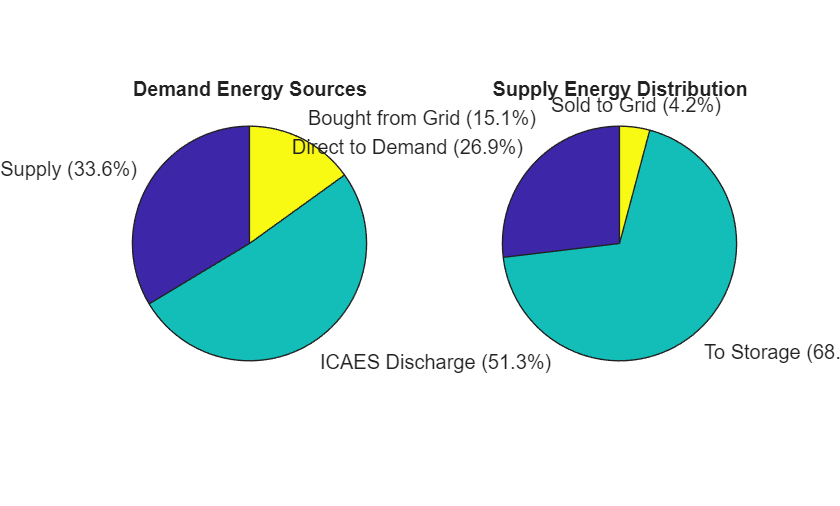

%% Figure 3 — Energy Pie Charts
figure('Name', 'Energy Sources and Supply Distribution', 'NumberTitle', 'off');

% Helper to build labelled pie (skips zero slices)
make_pie = @(data, labels) deal( ...
    data(data > 0), ...
    arrayfun(@(i) sprintf('%s (%.1f%%)', labels{i}, data(i)/sum(data(data>0))*100), ...
             find(data > 0), 'UniformOutput', false) );

% Left: Demand sources
subplot(1,2,1);
pie_d = [E_DirectSupply, E_ICAES, E_Bought];
lbl_d = {'Direct Supply', 'ICAES Discharge', 'Bought from Grid'};
if any(pie_d > 0)
    [d, l] = make_pie(pie_d, lbl_d);
    pie(d, l);
else
    pie(1, {'No Demand Data'});
end
title('Demand Energy Sources');

% Right: Supply distribution
subplot(1,2,2);
pie_s = [E_DirectSupply, E_ToStorage, E_Sold];
lbl_s = {'Direct to Demand', 'To Storage', 'Sold to Grid'};
if any(pie_s > 0)
    [d, l] = make_pie(pie_s, lbl_s);
    pie(d, l);
else
    pie(1, {'No Supply Data'});
end
title('Supply Energy Distribution');

 Charging/Discharging Duration Histogram

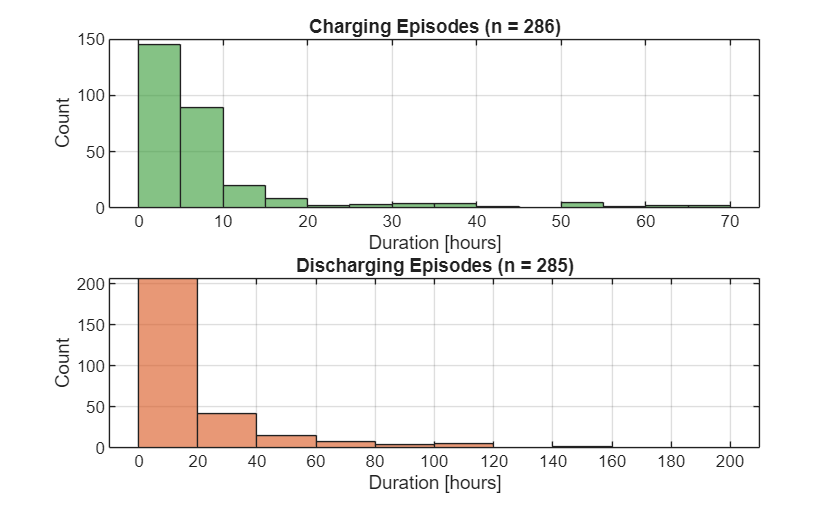

%% Charging & Discharging Episode Duration Histogram

dt_h = deltat / unit("h");  % timestep in hours

% Identify charging episodes (power going to storage > 0)
is_charging = P_ToStorage > 0;
d_ch = diff([0; is_charging(:); 0]);
ch_starts   = find(d_ch == 1);
ch_ends     = find(d_ch == -1) - 1;
ch_durations = (ch_ends - ch_starts + 1) * dt_h;

% Identify discharging episodes (ICAES delivering power > 0)
is_discharging = P_ICAES > 0;
d_dis = diff([0; is_discharging(:); 0]);
dis_starts   = find(d_dis == 1);
dis_ends     = find(d_dis == -1) - 1;
dis_durations = (dis_ends - dis_starts + 1) * dt_h;

% Plot
figure('Name', 'Charge/Discharge Episode Durations', 'NumberTitle', 'off');

subplot(2,1,1);
histogram(ch_durations, 'FaceColor', [0.2 0.6 0.2]);
title(sprintf('Charging Episodes (n = %d)', length(ch_durations)));
xlabel('Duration [hours]'); ylabel('Count'); grid on;

subplot(2,1,2);
histogram(dis_durations, 'FaceColor', [0.85 0.33 0.1]);
title(sprintf('Discharging Episodes (n = %d)', length(dis_durations)));
xlabel('Duration [hours]'); ylabel('Count'); grid on;


fprintf('Charging  — median: %.1f h, max: %.1f h, total episodes: %d\n', ...
    median(ch_durations), max(ch_durations), length(ch_durations));

Charging  — median: 4.8 h, max: 67.6 h, total episodes: 286


fprintf('Discharging — median: %.1f h, max: %.1f h, total episodes: %d\n', ...
    median(dis_durations), max(dis_durations), length(dis_durations));

Discharging — median: 6.2 h, max: 185.1 h, total episodes: 285


Surplus/Deficit Heatmap (Hour-of-Day vs Day)

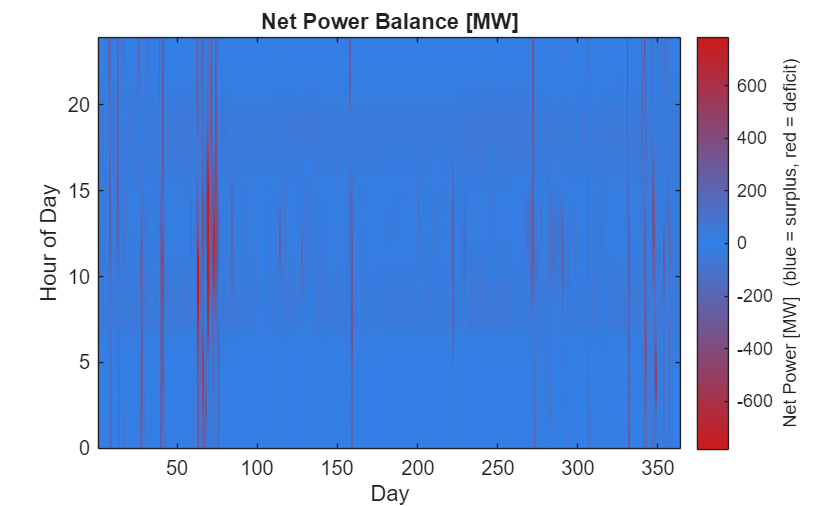

%% Heatmap: Net Power Balance by Hour-of-Day vs Day

P_net = (PSupply - PDemand) / unit("MW");  % positive = surplus, negative = deficit
dt_h  = deltat / unit("h");

steps_per_day = round(24 / dt_h);
n_days   = floor(length(P_net) / steps_per_day);
n_points = n_days * steps_per_day;

% Reshape into matrix: rows = time-of-day, columns = day
heatmap_data = reshape(P_net(1:n_points), steps_per_day, n_days);

hours_axis = (0:steps_per_day-1) * dt_h;
days_axis  = 1:n_days;

figure('Name', 'Net Power Heatmap', 'NumberTitle', 'off');
imagesc(days_axis, hours_axis, heatmap_data);
set(gca, 'YDir', 'normal');

% Built-in diverging red-white-blue colormap (no toolbox needed)
n = 256; half = n/2;
cmap = [linspace(0.8, 0.2, half)', linspace(0.1, 0.5, half)', linspace(0.1, 0.9, half)'; ...
        linspace(0.2, 0.8, half)', linspace(0.5, 0.1, half)', linspace(0.9, 0.1, half)'];
colormap(cmap);

% Centre the colorscale on zero so surplus/deficit are symmetric
clim_val = max(abs(heatmap_data(:)));
clim([-clim_val, clim_val]);

cb = colorbar;
cb.Label.String = 'Net Power [MW]  (blue = surplus, red = deficit)';
xlabel('Day'); ylabel('Hour of Day');
title('Net Power Balance [MW]');

Unmet Demand

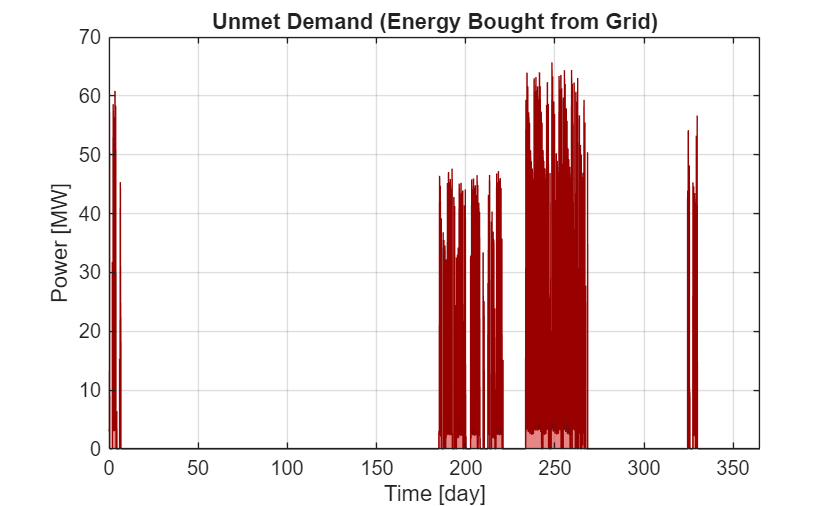

%% Unmet Demand (power bought from grid)

figure('Name', 'Unmet Demand', 'NumberTitle', 'off');

area(tout/unit("day"), PBuy/unit("MW"), 'FaceColor', [0.85 0.2 0.2], 'FaceAlpha', 0.6);
hold on;
plot(tout/unit("day"), PBuy/unit("MW"), 'Color', [0.6 0 0], 'LineWidth', 0.5);
xlim([0 tout(end)/unit("day")]); grid on;
title('Unmet Demand (Energy Bought from Grid)');
xlabel('Time [day]'); ylabel('Power [MW]');


% Statistics
n_unmet = sum(PBuy > 0);
n_total = length(PBuy);
pct_time_unmet = n_unmet / n_total * 100;
peak_unmet = max(PBuy) / unit("MW");

fprintf('Unmet demand events: %d of %d timesteps (%.1f%% of time)\n', n_unmet, n_total, pct_time_unmet);

Unmet demand events: 17419 of 105118 timesteps (16.6% of time)


fprintf('Peak unmet demand: %.1f MW\n', peak_unmet);

Peak unmet demand: 65.7 MW


Rolling Self-Sufficiency

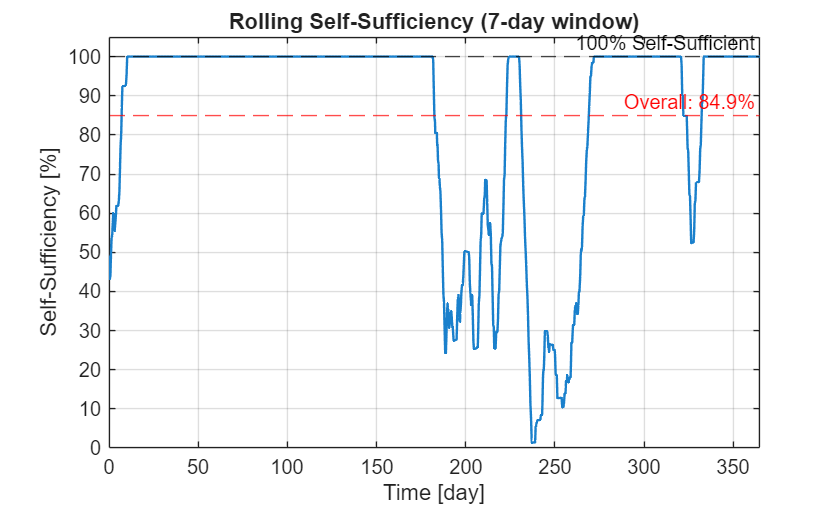

%% Rolling Self-Sufficiency (7-day window)

dt_h = deltat / unit("h");
window_hours = 24 * 7;                          % 7-day rolling window
window_steps = round(window_hours / dt_h);

% Recalculate overall self-sufficiency if it doesn't exist in the workspace
if ~exist('self_sufficiency', 'var')
    P_DirectSupply = min(PSupply, PDemand);
    P_Deficit = max(0, PDemand - PSupply);
    P_ICAES = max(0, P_Deficit - PBuy);
    
    E_DirectSupply = sum(P_DirectSupply);
    E_ICAES = sum(P_ICAES);
    E_TotalDemand = sum(PDemand);
    self_sufficiency = (E_DirectSupply + E_ICAES) / E_TotalDemand * 100;
end

% Rolling sums using movsum
rolling_demand  = movsum(PDemand, window_steps);
rolling_bought  = movsum(PBuy,    window_steps);
rolling_self_suff = (1 - rolling_bought ./ rolling_demand) * 100;

% Avoid division artifacts where demand is near zero
rolling_self_suff(rolling_demand < 1e-6) = 100;

figure('Name', 'Rolling Self-Sufficiency', 'NumberTitle', 'off');
plot(tout/unit("day"), rolling_self_suff, 'Color', [0.1 0.5 0.8], 'LineWidth', 1.2);
yline(100, '--k', '100% Self-Sufficient');
yline(self_sufficiency, '--r', sprintf('Overall: %.1f%%', self_sufficiency));
xlim([0 tout(end)/unit("day")]); ylim([0 105]); grid on;
title('Rolling Self-Sufficiency (7-day window)');
xlabel('Time [day]'); ylabel('Self-Sufficiency [%]');

### Plot: Deficit vs. ICAES Discharging Power

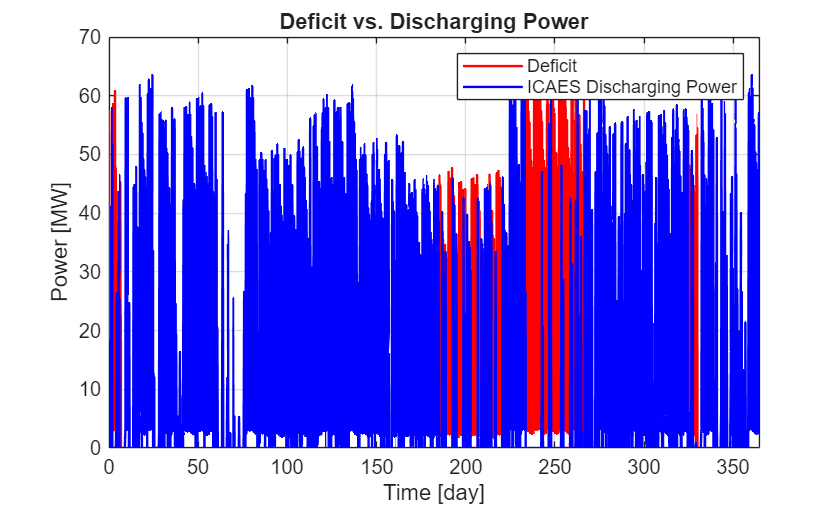

%% Figure 4 — Deficit vs. ICAES Discharging Power
figure('Name', 'Deficit vs. Discharging Power', 'NumberTitle', 'off');

plot(tout/unit("day"), P_Deficit/unit("MW"), 'r', 'LineWidth', 1.2); hold on;
plot(tout/unit("day"), P_ICAES/unit("MW"),   'b', 'LineWidth', 1.2);
xlim([0 tout(end)/unit("day")]); grid on;
title('Deficit vs. Discharging Power');
xlabel('Time [day]'); ylabel('Power [MW]');
legend('Deficit', 'ICAES Discharging Power');

 (replaces your existing efficiency block)

## EST Efficiency + Loss Breakdown

%% E%% EST System Efficiency & Energy Loss Breakdown

E_Surplus = sum(P_Surplus);
eta_EST = E_ICAES / E_Surplus * 100;

E_TotalDemand      = sum(PDemand);
E_MetWithoutBuying = E_DirectSupply + E_ICAES;
self_sufficiency   = E_MetWithoutBuying / E_TotalDemand * 100;

fprintf('Total surplus available  : %.2f\n', E_Surplus);

Total surplus available  : 2305675783052.00


fprintf('Energy discharged (ICAES): %.2f\n', E_ICAES);

Energy discharged (ICAES): 1294547365499.33


fprintf('Round-trip efficiency    : %.1f%%\n', eta_EST);

Round-trip efficiency    : 56.1%


fprintf('Self-sufficiency ratio   : %.1f%%\n', self_sufficiency);

Self-sufficiency ratio   : 84.9%


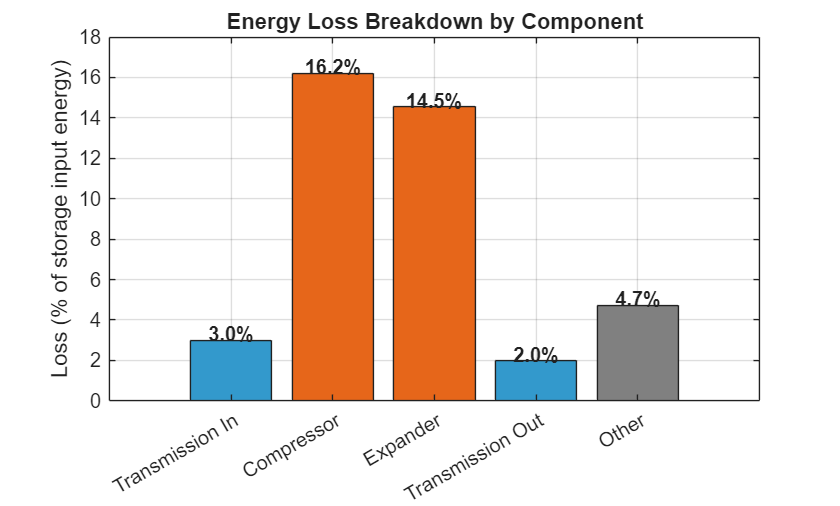


% --- Loss attribution through the conversion chain ---
%   Surplus → [Tran In] → [Compressor] → Stored → [Expander] → [Tran Out] → Demand
E_in       = E_ToStorage;
L_tran_in  = E_in * (1 - eta_tran);
L_comp     = E_in * eta_tran * (1 - eta_comp);
L_exp      = E_in * eta_tran * eta_comp * (1 - eta_exp);
L_tran_out = E_in * eta_tran * eta_comp * eta_exp * (1 - eta_tran);
E_out_theo = E_in * eta_tran * eta_comp * eta_exp * eta_tran;
L_other    = max(0, E_out_theo - E_ICAES);  % capacity / thermodynamic losses

losses     = [L_tran_in, L_comp, L_exp, L_tran_out, L_other];
loss_pct   = losses / E_in * 100;
categories = {'Transmission In', 'Compressor', 'Expander', 'Transmission Out', 'Other'};

figure('Name', 'Energy Loss Breakdown', 'NumberTitle', 'off');
b = bar(loss_pct, 'FaceColor', 'flat');
b.CData = [0.2 0.6 0.8; 0.9 0.4 0.1; 0.9 0.4 0.1; 0.2 0.6 0.8; 0.5 0.5 0.5];
set(gca, 'XTickLabel', categories);
ylabel('Loss (% of storage input energy)');
title('Energy Loss Breakdown by Component');
grid on;
for i = 1:length(loss_pct)
    text(i, loss_pct(i) + 0.3, sprintf('%.1f%%', loss_pct(i)), ...
        'HorizontalAlignment', 'center', 'FontWeight', 'bold');
end